sympref('FloatingPointOutput',true);
state_space_modelling;   %Calling the state space model file

sys =
 
  A = 
          x1     x2     x3     x4
   x1      0      1      0      0
   x2      0      0      0      0
   x3      0      0      0      1
   x4      0      0  1.838      0
 
  B = 
       u1
   x1   0
   x2   1
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



af =          0    1.0000         0         0
    0.0000         0    1.0000         0
         0   -0.0000         0    1.0000
    0.0000         0    1.8375         0


bf =          0
         0
         0
    1.0000


cf =    -1.8375         0    1.0000         0
    0.0000         0    1.0000         0


df =      0
     0


z=eig(A)    % One of the open loop poles is in the right half of the plane

z =     1.3555
   -1.3555
         0
         0


% showing that the system is unstable

wn = 4.66;
zeta=0.858;
tau = 1/(zeta*wn)   % Time constant

tau = 0.2501

ts = 4/(wn*zeta)    % Settling time using design parameters

ts = 1.0004

p1 = -(wn*zeta)+wn*sqrt((0.858^2)-1)     % Dominant pole calculation

p1 = -3.9983 + 2.3936i

p2 = -(wn*zeta)-wn*sqrt((0.858^2)-1)

p2 = -3.9983 - 2.3936i

sep_factor=2;
a=sep_factor*zeta*9.3;
b=(sep_factor*wn)^2;
syms s
eqn = s^2+a*s+b == 0;
y=solve(eqn,s);     % Non-dominant poles calculation
p3=y(1) 

$$p3 = -7.9794-4.8158\,\mathrm{i}$$

p4=y(2)

$$p4 = -7.9794+4.8158\,\mathrm{i}$$

co=ctrb(sys)

co =          0    1.0000         0         0
    1.0000         0         0         0
         0    1.0000         0    1.8375
    1.0000         0    1.8375         0


controllability = rank(co);
desired_char_eqn = expand((s-p3)*(s-p4)*(s-p1)*(s-p2))

$$desired\_char\_eqn = s^{4}+23.9554\,s^{3}+236.1935\,s^{2}+1.0412e+03\,s+1.8863e+03$$

syms k1 k2 k3 k4
det(s*eye(4)-A+B*[k1 k2 k3 k4]) % From control law

$$ans = k_{1}\,s^{2}-1.8375\,k_{2}\,s-1.8375\,k_{1}+k_{2}\,s^{3}+k_{3}\,s^{2}+k_{4}\,s^{3}-1.8375\,s^{2}+s^{4}$$

%Comparing values of desired characteristic equation and the resulting matrix from 
% |SI-A+BK| to find the control equation matrix
k1=-1027.42;
k2=-566.911;
k3=1265.275;
k4=589.911;
k=[k1 k2 k3 k4];

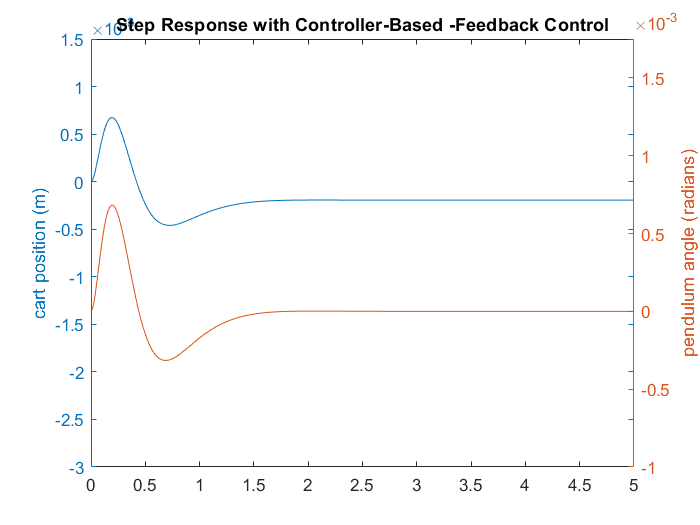

% Controller Design
states = {'x' 'x_dot' 'phi' 'phi_dot'};
inputs = {'r'};
outputs = {'x'; 'phi'};

sys_cl = ss(A-B*k,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

t = 0:0.01:5;
r =0.2*ones(size(t));
[y,t,x]=lsim(sys_cl,r,t);
[AX,H1,H2] = plotyy(t,y(:,1),t,y(:,2),'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)')
set(AX(1),'YLim',[-0.00300 0.00150])
set(AX(1),'YTick',-0.003:0.0005:0.0015)
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)')
set(AX(2),'YLim',[-0.00100 0.00175])
set(AX(2),'YTick',-0.001:0.0005:0.0018)
title("Step Response with Controller-Based -Feedback Control")

% Integral Design
Cn = [1 0 0 0];
sys_ss = ss(A,B,Cn,0);
Nbar = rscale(sys_ss,k)

Nbar = -1.0274e+03

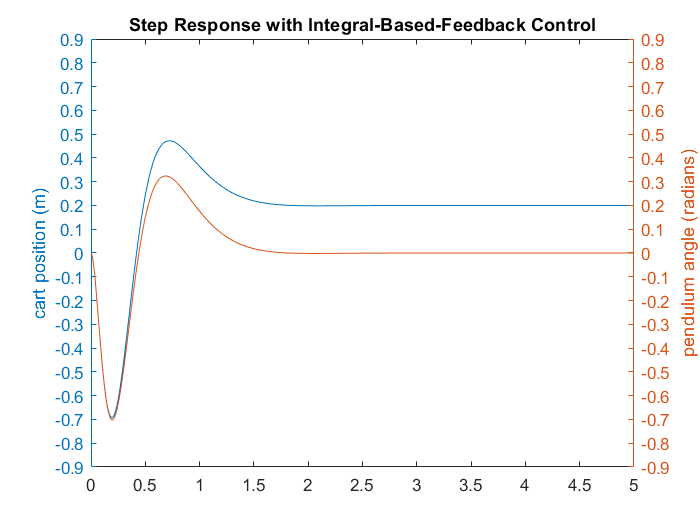

states = {'x' 'x_dot' 'phi' 'phi_dot'};
inputs = {'r'};
outputs = {'x'; 'phi'};

sys_cl = ss(A-B*k,B*Nbar,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

t = 0:0.01:5;
r =0.2*ones(size(t));
[y,t,x]=lsim(sys_cl,r,t);
[AX,H1,H2] = plotyy(t,y(:,1),t,y(:,2),'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)')
set(AX(1),'YLim',[-0.9 0.9])
set(AX(1),'YTick',-0.9:0.1:0.9)
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)')
set(AX(2),'YLim',[-0.9 0.9])
set(AX(2),'YTick',-0.9:0.1:0.9)
title("Step Response with Integral-Based-Feedback Control")

% Observer Design
P=[-40 -41 -42 -43];
Ke = place(A',C',P)'

Ke = 	1.0e+03 *

    0.0829    0.0011
    1.7161    0.0443
    0.0009    0.0831
    0.0380    1.7287


Ace = [(A-B*k) (B*k); zeros(size(A)) (A-Ke*C)]

Ace = 	1.0e+03 *

         0    0.0010         0         0         0         0         0         0
    1.0274    0.5669   -1.2653   -0.5899   -1.0274   -0.5669    1.2653    0.5899
         0         0         0    0.0010         0         0         0         0
    1.0274    0.5669   -1.2634   -0.5899   -1.0274   -0.5669    1.2653    0.5899
         0         0         0         0   -0.0829    0.0010   -0.0011         0
         0         0         0         0   -1.7161         0   -0.0443         0
         0         0         0         0   -0.0009         0   -0.0831    0.0010
         0         0         0         0   -0.0380         0   -1.7268         0


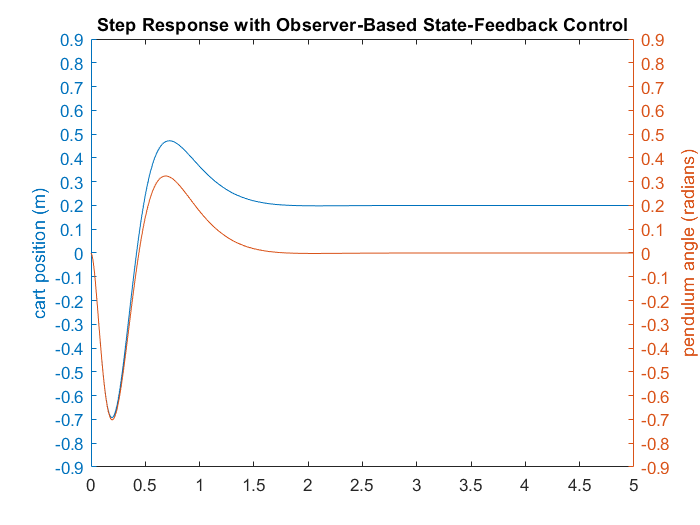

Bce = [B*Nbar; zeros(size(B))];
Cce = [C zeros(size(C))];
Dce = [0;0];

states = {'x' 'x_dot' 'phi' 'phi_dot' 'e1' 'e2' 'e3' 'e4'};
inputs = {'r'};
outputs = {'x'; 'phi'};

sys_est_cl = ss(Ace,Bce,Cce,Dce,'statename',states,'inputname',inputs,'outputname',outputs);

t = 0:0.01:5;
r = 0.2*ones(size(t));
[y,t,x]=lsim(sys_est_cl,r,t);
[AX,H1,H2] = plotyy(t,y(:,1),t,y(:,2),'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)')
set(AX(1),'YLim',[-0.9 0.9])
set(AX(1),'YTick',-0.9:0.1:0.9)
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)')
set(AX(2),'YLim',[-0.9 0.9])
set(AX(2),'YTick',-0.9:0.1:0.9)
title('Step Response with Observer-Based State-Feedback Control')